# **TU: Kurtogram and Spectral Kurtosis **

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Time-Frequency Preprocessing and Features of 

- Kurtogram

- Spectral Kurtosis

> Revise STFT and FFT  before this tutorial

## Include path

addpath('../../Library')  

# **Kurtogram**

## Dataset

A chirp signal from 100 to 200 Hz in 10 sec. Add gaussian random noise.

fs= 1e3;
ts = 0:1/fs:10;
f0 = 100;
f1 = 200;


%x = chirp(ts,f0,1,f1,'quadratic',[],'concave');
xc = chirp(ts,f0,1,f1);
x = xc+randn(1,length(ts));

## Exercise 1: Plot Kurtogram

Plot the kurtogram using the sample rate `fs`.

A high kurtosis level corresponds to a high level of nonstationary or non-Gaussian behavior. 

%%% YOUR CODE GOES HERE
% kurtogram( )

Explore the effects of lowering the maximum level to 5.

level = 5;

%%% YOUR CODE GOES HERE
% kurtogram()

# **Spectral Kurtosis**

## Exercise 2: Plot the spectral kurtosis.

Use the default window size.

%%% spectral kurtosis
% YOUR CODE GOES HERE
% pkurtosis(_____)    % your code goes here

title('Spectral Kurtosis with Default Window Size')


Choose  the optimal window size using kurtogram.

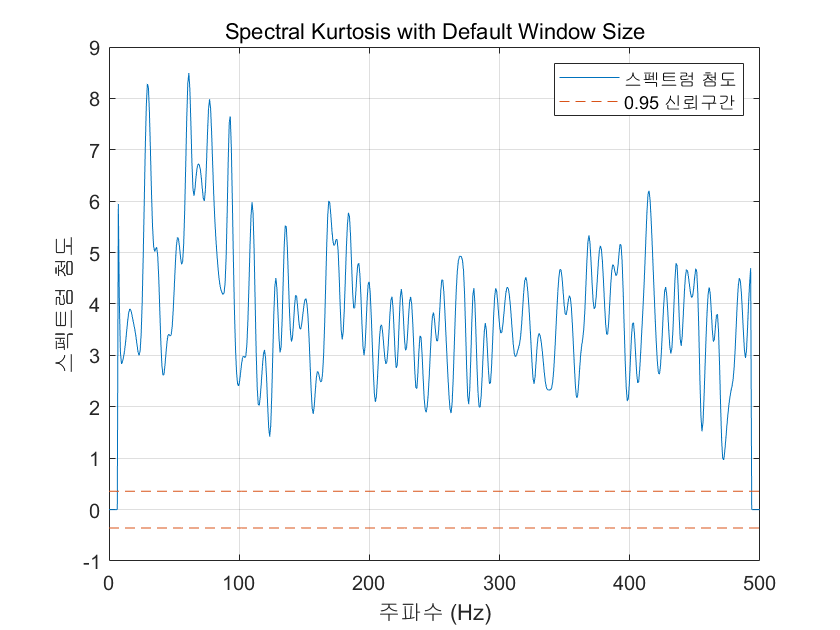

[kgram,f,w,fc,wc,bw] = kurtogram(x);

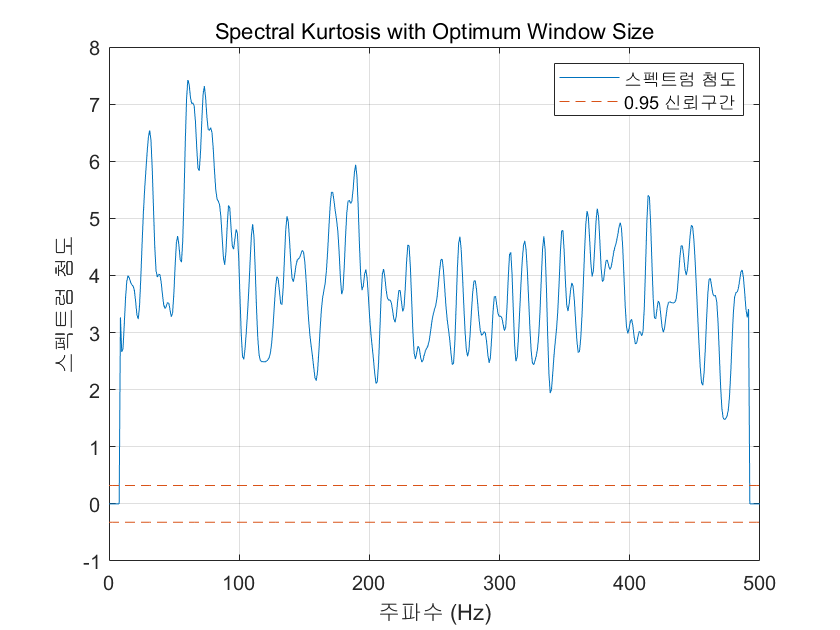


%%% Draw spectral kurtosis with 'wc' window size
% YOUR CODE GOES HERE
% pkurtosis(_____)    % your code goes here

title('Spectral Kurtosis with Optimum Window Size')